# LEO Satellite Tracking Simulation

### This program was developed as part of a semester assignment for the course *Advanced Control Systems (ECE_ELE760) *during the 2024-2025 academic year.

University of the Peloponeese

School of Electrical & Computer Engineering

Ioannis Ziangas, Undergraduate Student

Supervisor: Georgios Souliotis, Associate Professor

## **Clear The Workspace**

We first clear the workspace and close all previous pictures that may have been left open.

clc; clear; close all; close all hidden;

## **Create a Satellite Scenario**

Here we define the parameters for how long will the satellite simulation will run for.

startTime = datetime(2025, 1, 4, 0, 0, 0);                  % Define the start time (Year, Month, Day, Hour, Minute, Second)
stopTime = startTime + minutes(25);                         % Define the stop time (simulation duration is 25 minutes)
sampleTime = 1;                                             % Define the sample time (1-second intervals)
sc = satelliteScenario(startTime, stopTime, sampleTime);    % Create the satellite scenario with the specified parameters.

## **Create The Satellite Orbit Based on TLE**

We create the satellite orbit based on the Two Line Elements (TLE) format. The orbit propagator is the default Simplified Perturbations Models 4 **(SGP4).**

a = earthRadius + 550e3;    % Semi-major axis (550 km above Earth's radius)
eccentricity = 0;           % Eccentricity (circular orbit)
inclination = 40;           % Inclination angle (degrees)
RAAN = 10;                   % Right Ascension of the Ascending Node
argofperiapsis = 70;         % Argument of Periapsis
trueanomaly = 0;            % True anomaly (initial position)
sat1 = satellite(sc, a, eccentricity, inclination, RAAN, argofperiapsis, trueanomaly, "Name", "Satellite", "OrbitPropagator","sgp4");

## **Creating a Ground Station**

We create a ground station which will track the satellite once it ender its local horizon

% Create a ground station to track the satellite and establish an uplink connection.
lat = 38.21868;          % Latitude of the ground station
lon = 21.74641;          % Longitude of the ground station
alt = 0;                 % Altitude (sea level)
minEl = 10;              % Minimum elevation angle (degrees)
gs = groundStation(sc, 'Latitude', lat, ...
                       'Longitude', lon, ...
                       'Altitude', alt, ...
                       'MinElevationAngle', minEl, ...
                       'Name', "Patras HQ");

## **Satellite Access**

We can check the connections of our ground station that has made with the satellite. 

% Obtain the azimuth, elevation and range
% Calculate the access intervals and parameters between the satellite and the ground station.
% Obtain the azimuth, elevation, range, and times of access.
[az, el, range, timeOut] = aer(gs, sat1);
ac = access(sat1, gs);                 % Compute access data between satellite and ground station
intvls = accessIntervals(ac);          % Display intervals of access
timeArray = intvls.StartTime:seconds(sampleTime):intvls.EndTime; % Create time array for the access intervals
timeArray.Format = 'dd-MM-yyyy HH:mm:ss'; % Format the time for readability

% Pre-allocate arrays for azimuth, elevation, and range
azim = zeros(1, length(timeArray)); 
elev = zeros(1, length(timeArray)); 
r = zeros(1, length(timeArray));

% Calculate azimuth, elevation, and range for each time step
for i = 1:length(timeArray)
    [azim(i), elev(i), r(i)] = aer(gs, sat1, timeArray(i));
end

## **Plot the Satellite Pass**

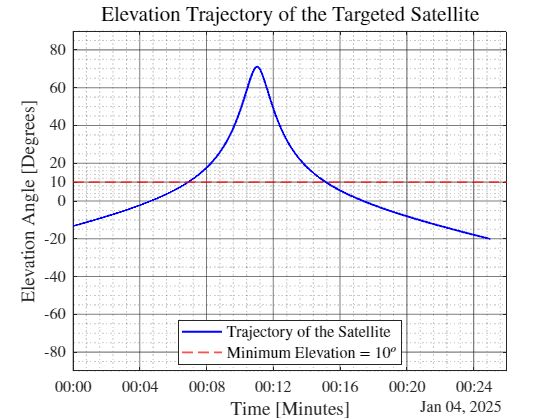

% Plot the Satellite Pass
% Time vector for the entire simulation
t = startTime:seconds(sampleTime):stopTime; 

% Create the plot
figure; % Create a new figure
hold on;
plot(t, el, 'b-', 'LineWidth', 1.5);           % Plot the satellite's elevation angle
yline(minEl, '--r', 'LineWidth', 1.2);         % Add a horizontal line for the minimum elevation angle

% Configure grid and axes for publication quality
grid on;                                        % Enable grid
ax = gca;                                       % Get current axes
ax.GridAlpha = 0.6;                             % Adjust grid transparency
ax.GridLineWidth = 0.8;                         % Make grid lines slightly bold
ax.MinorGridLineStyle = ':';                    % Add minor grid lines
ax.XMinorGrid = 'on';                           % Enable minor grid for x-axis
ax.YMinorGrid = 'on';                           % Enable minor grid for y-axis
ax.FontSize = 12;                               % Set font size for better readability
ax.FontName = 'Times New Roman';                % Use a standard font for publication
ax.TickLabelInterpreter = 'latex';              % Use LaTeX for tick labels

% Label axes
xlabel("Time [Minutes]", 'Interpreter', 'latex', 'FontSize', 14); % Label x-axis
ylabel("Elevation Angle [Degrees]", 'Interpreter', 'latex', 'FontSize', 14); % Label y-axis

% Add title
title("Elevation Trajectory of the Targeted Satellite", 'Interpreter', 'latex', 'FontSize', 16);

% Configure y-axis limits and ticks
ylim([-90 90]);                                 % Set y-axis range
if ~ismember(minEl, yticks)                     % Ensure minimum elevation is included in y-axis ticks
    yticks(sort([yticks minEl]));               % Add minimum elevation to y-ticks and sort
end

% Add legend
legend("Trajectory of the Satellite", ...
       "Minimum Elevation = " + minEl + "$^{o}$", ...
       "Location", "best", 'Interpreter', 'latex', 'FontSize', 12);

% Beautify the figure for publication
set(gcf, 'Color', 'w');                         % Set figure background to white
box on;                                         % Add a border around the plot
hold off;

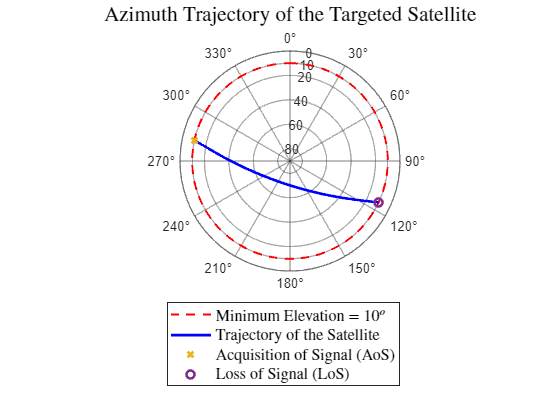

% Close all previous figures to avoid interference with the polar plot
close all;

% Create a Polar Plot of the Azimuth Angles
% Define azimuth angles for a complete circle (0 to 360 degrees).
azimuthAngles = linspace(0, 360, 1000);

% Create the polar axes
ax = polaraxes;
hold on; % Allow multiple plots on the same axes

% Plot the minimum elevation circle
polarplot(deg2rad(azimuthAngles), repmat(minEl, size(azimuthAngles)), 'r--', 'LineWidth', 1.5);

% Plot the azimuth vs elevation
polarplot(azim * pi / 180, elev, 'b-', 'LineWidth', 2); % Convert azimuth to radians for the polar plot
polarplot(azim(1) * pi / 180, elev(1), 'x', 'LineWidth', 2);
polarplot(azim(end) * pi / 180, elev(end), 'o', 'LineWidth', 2);

% Checking if the minEl value is already plotted otherwise it plots it
% along with the default r values.
if ~ismember(minEl, rticks)
    rticks(sort([rticks minEl]));
end

% Configure the polar axes
pax = gca;
pax.GridAlpha = 0.4;
ax.RDir = 'reverse';                     % Reverse radial direction (elevation decreases outward)
ax.ThetaDir = 'clockwise';               % Azimuth angle increases clockwise
ax.ThetaZeroLocation = 'top';            % Place azimuth 0° at the top (North)
ax.RAxis.Limits = [0 90];                % Set radial axis limits (elevation range: 0-90 degrees)
title("Azimuth Trajectory of the Targeted Satellite", 'Interpreter', 'latex', 'FontSize', 16); % Add title to the plot
legend("Minimum Elevation = " + minEl + "$^{o}$", ...
        "Trajectory of the Satellite", ...
        "Acquisition of Signal (AoS)", ...
        "Loss of Signal (LoS)", ...
        'Location', 'southoutside', ...
        'Interpreter', 'latex', 'FontSize', 12); % Add legend
hold off; % Release hold

## **Simulating The Satellite Scenario**

We can simulate the satellite orbit and ground station.

play(sc);